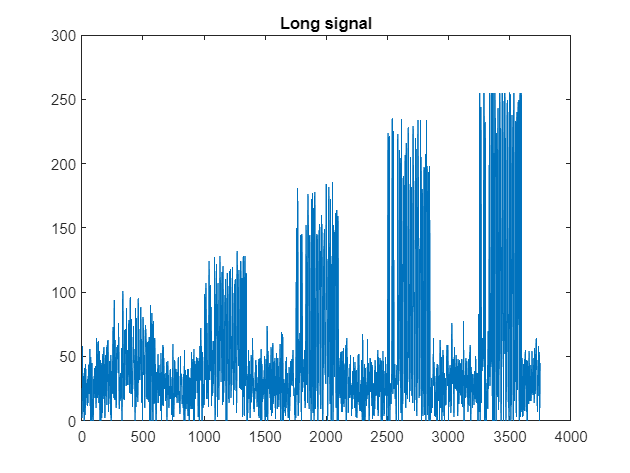

clear
load("tempNeigiamasRodiklisData.mat")

minAmplitude = 0.2;
maxAmplitude = 1.1;
stepCount = 5;

dataSend = "101101110101010101011000111";
singleSigLength = 750;
ADCsignalLong = zeros(1, stepCount*singleSigLength);
idealSignalLong = zeros(1, stepCount*singleSigLength);
for generuojama_amplitude_index = 1:stepCount
    generatedAmplitude = minAmplitude + (maxAmplitude - minAmplitude)/(stepCount-1) * (generuojama_amplitude_index-1);
    [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, generatedAmplitude);
    copyIndexStart = singleSigLength*(generuojama_amplitude_index-1)+1;
    copyIndexLast = singleSigLength*(generuojama_amplitude_index);
    ADCsignalLong(copyIndexStart:copyIndexLast) = ADCsignal;
    idealSignalLong(copyIndexStart:copyIndexLast) = idealSignal(1:10:length(idealSignal));
end
plot(ADCsignalLong)
title("Long signal")

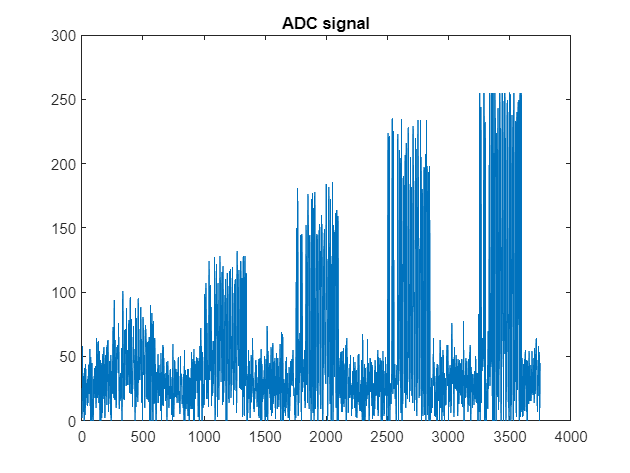

figure
plot(ADCsignalLong)
title("ADC signal")

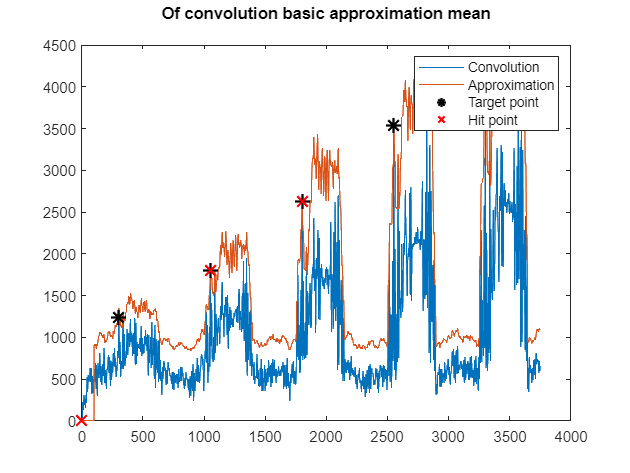

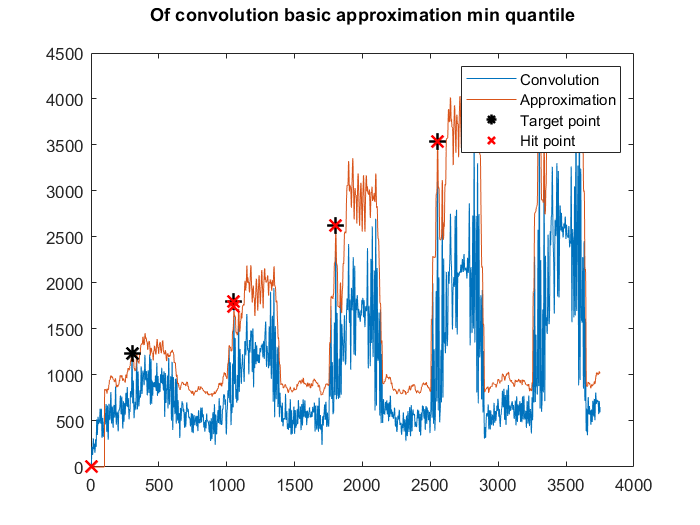

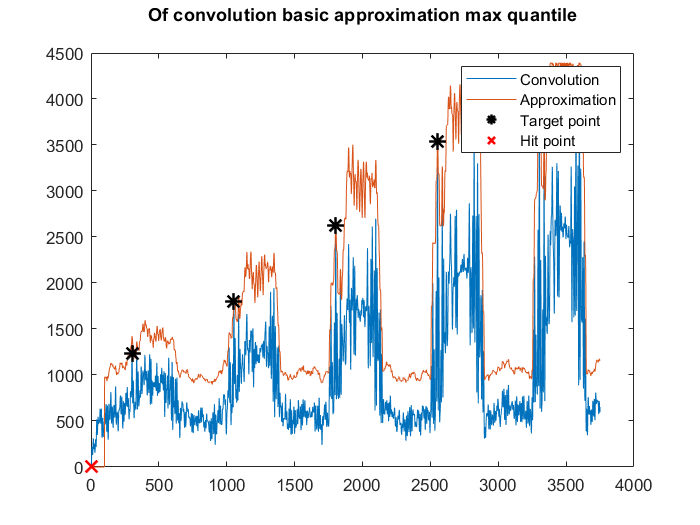

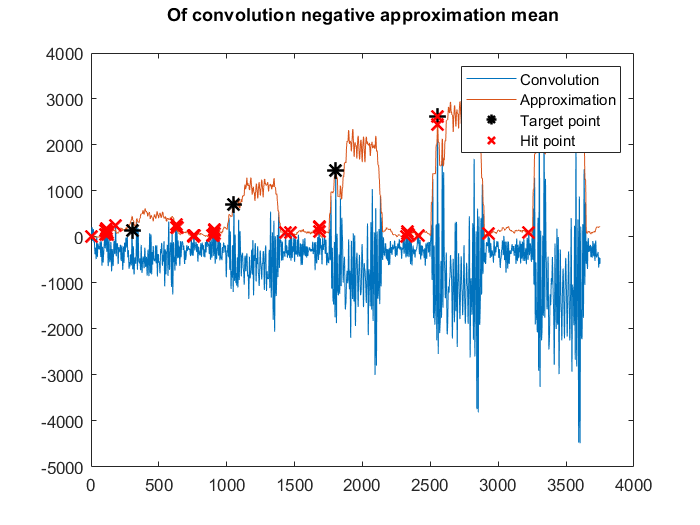

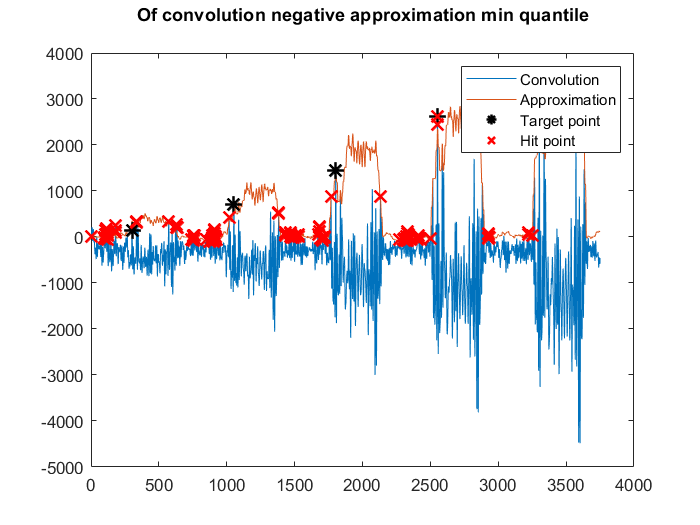

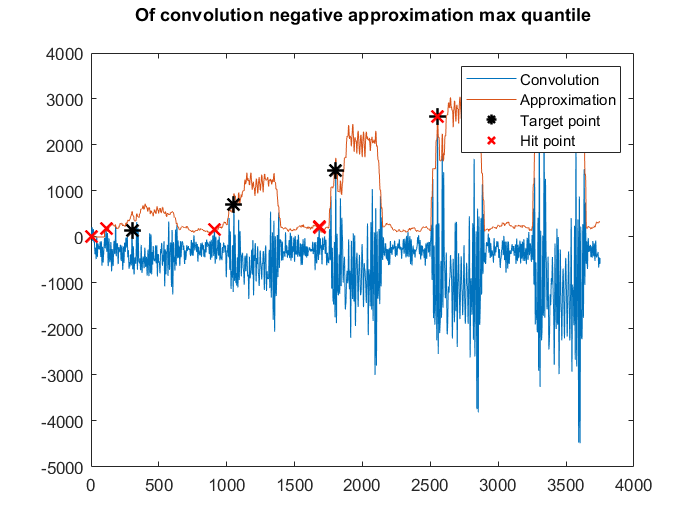

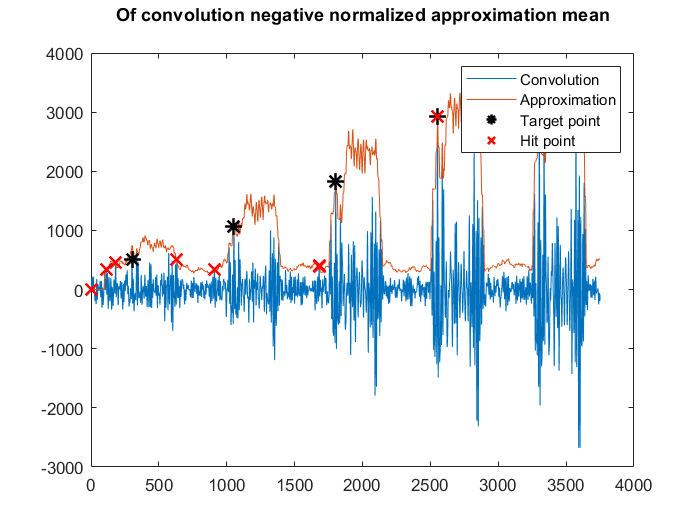

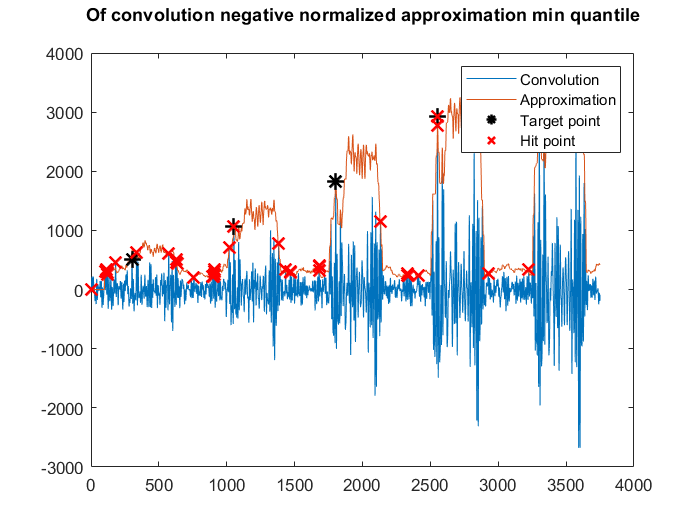

for convIndex = 1:uint32(ConvolutionEnum.last)
    for approxIndex = 1:uint32(ApproximationEnum.last)
        approximationIndex = (convIndex-1) * uint32(ApproximationEnum.last) + approxIndex;
        coeficientAmount = length(allApproximations(approximationIndex).coeficients);
        windowLength = length(convTypes(convIndex).convPreambule);
        currentConvolution = GenerateConv(ADCsignalLong, convTypes(convIndex).convPreambule);
        currentEnergy = zeros(1, length(ADCsignalLong));
        currentApproximation = zeros(1, length(ADCsignalLong));
        for i = 100:length(currentEnergy)
            energyMaxPoint = i;
            energyMinPoint = i - windowLength;
            currentEnergy(i) = sum(abs(ADCsignalLong(energyMinPoint : energyMaxPoint) .* ADCsignalLong(energyMinPoint : energyMaxPoint)));
            currentApproximation(i) = currentEnergy(i)^2*allApproximations(approximationIndex).coeficients(1)+currentEnergy(i)*allApproximations(approximationIndex).coeficients(2)+allApproximations(approximationIndex).coeficients(3);
        end
        hitPointsX = zeros(1, length(ADCsignalLong));
        hitPointsY = zeros(1, length(ADCsignalLong));
        hitPointsIndex = 1;
        for ii = 100:length(ADCsignalLong)
            if currentConvolution(ii) > currentApproximation(ii)
                hitPointsX(hitPointsIndex) = ii;
                hitPointsY(hitPointsIndex) = currentConvolution(ii);
                hitPointsIndex = hitPointsIndex + 1;
            end
        end
        hitPointsX = hitPointsX(1:hitPointsIndex);
        hitPointsY = hitPointsY(1:hitPointsIndex);
        targetPointsX = zeros(1, stepCount);
        targetPointsY = zeros(1, stepCount);
        for ii = 1:stepCount
            targetPointsX(ii) = convTypes(convIndex).expectedMaximum + length(ADCsignal) * (ii-1);
            targetPointsY(ii) = currentConvolution(targetPointsX(ii));
        end

        figure
        plot(currentConvolution, 'DisplayName', "Convolution")
        hold on
        %plot(currentEnergy, 'DisplayName', "Energy")
        plot(currentApproximation, 'DisplayName', "Approximation")
        scatter(targetPointsX, targetPointsY,100,"*", "black",'LineWidth', 1.5, 'DisplayName', "Target point")
        scatter(hitPointsX, hitPointsY,100,"x", "red",'LineWidth', 1.5, 'DisplayName', "Hit point")
        hold off
        title(sprintf("Of convolution %s approximation %s\n", convTypes(convIndex).name, allApproximations(approximationIndex).name));
        legend
    end
end


%p_fitt = 2000^2*p(1)+2000*p(2)+p(3)%-1285.4 + 3000*1.0267